# Leveraging the MathWorks Robust Control Toolbox for the Quanser Magnetic Levitation 

The [Quanser Magnetic Levitation](https://www.quanser.com/products/magnetic-levitation/), or Maglev, is shown below is a one-dimensional magnetic levitation system. It has an optical ball position sensor and a current sensor to measure the current in the electromagnet coils.

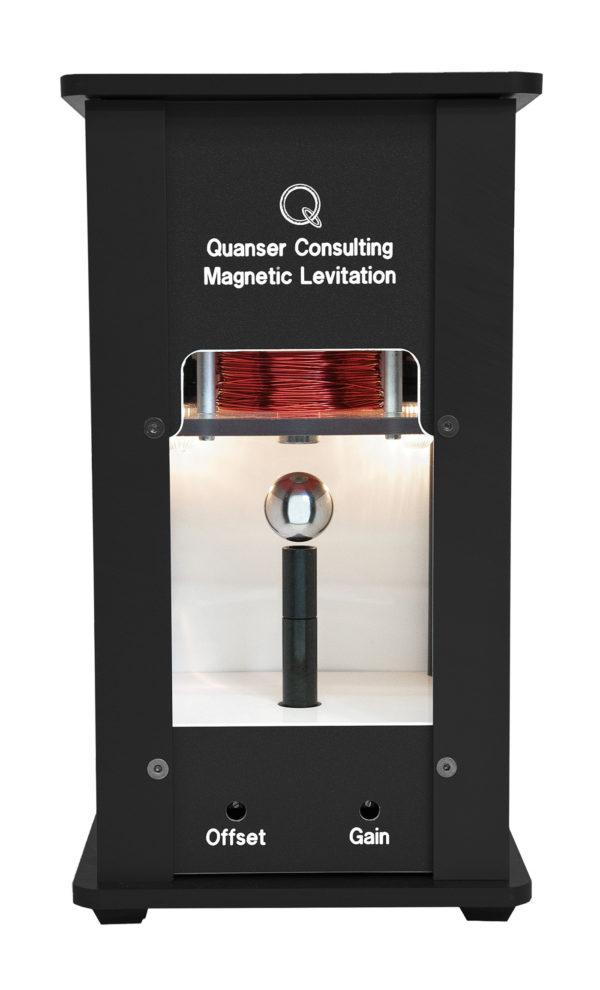

The Maglev system is a challenging control systems application for several reasons:

- Nonlinear dynamics.

- Ball levitation is unstable.

- Uncertainties: Electromagnetic force acting on the ball changes quickly depending on the air gap, i.e., distance between the ball and the electromagnet, and the current applied in the coils. The force can also vary over time, i.e., magnet coil heats up and causes the inductance to increase. 

- Actuator dynamics: Large inductance of the electromagnet causes a huge delay in the actuator response. As a result, a current control is needed. In the ball position control design, we assume that the current in the coils equals the current commanded. However, even with the current control there is always a slight delay. 

- Sensor noise: Although small, there is still some noise in the current and ball position sensors.  

Given the inherit nonlinear dynamics and uncertainties, robust control techniques are often used in magnetic levitation and other similar applications. Here we show how to use the MathWorks® [Robust Control Toolbox](https://www.mathworks.com/products/robust.html?s_tid=srchtitle_robust%20control%20tuning_1)™ to define an uncertain variable and use the [Control System Tuner](https://www.mathworks.com/help/control/ref/controlsystemtuner-app.html) app to tune a robust controller that can help compensate for the variance in the magnet force constant and the other uncertainties that are not accounted for.

## Ball Position Model

The Quanser Magnetic Levitation System, i.e., Quanser Maglev, can be modeled as follows.

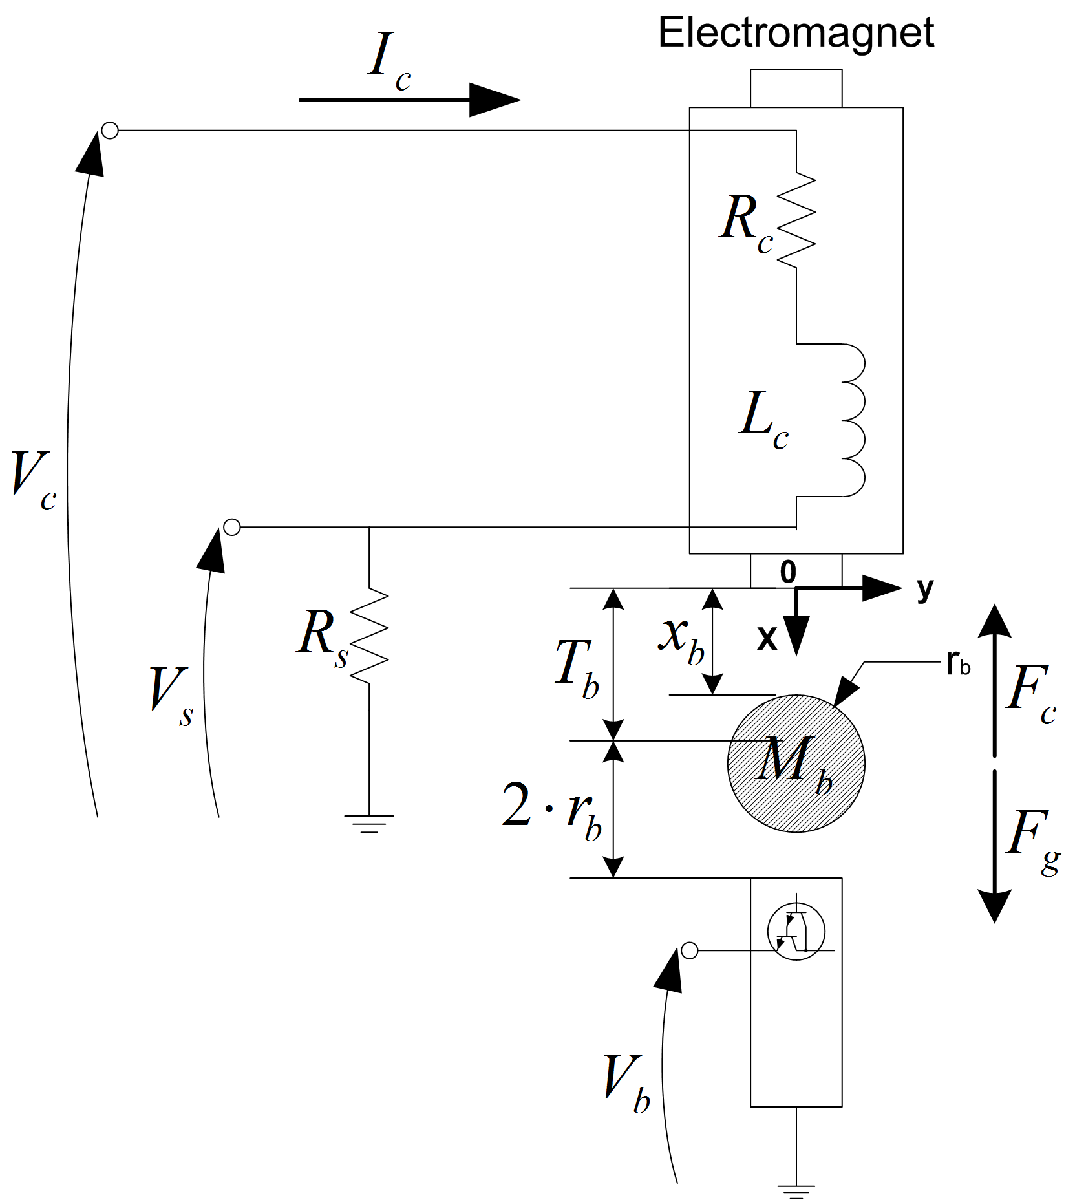

Using the notation and conventions shown above the attractive force generated by the electromagnet and acting on the steel ball can be expressed by


$$F_c = \frac{K_m i_c(t)^2}{x_b^2}$$


where $x_b
$ is the air gap between the ball and the face of the electromagnet and $K_m$ is the electromagnetic force constant. The pull of the electromagnet is proportional to the square of the current and inversely proportional to the air gap (i.e. ball position) squared. The force due to gravity acting on the ball is given by

$F_g = M_b g$.

The total external force experienced by the ball using the electromagnet is given by


$$F_{ext} = -F_c + F_g = -\frac{K_m i_c(t)^2}{x_b(t)^2} + M_b g.
$$
	

Applying then Newton's second law of motion to the ball gives the following nonlinear Equation Of Motion (EOM)


$$\ddot{x}_b(t) = -\frac{K_m i_c(t)^2}{M_b x_b(t)^2} + g.$$


The force constant can be derived from the measured current and air gap position. If the ball is maintained at an fixed position, $x_{b0}$, then a certain current is need to stabilize it to that point, $i_{c0}$. 


$$K_m=\frac{M_b g x_{b0}^2}{i_{c0}^2}$$


### Variable Electromagnet Force

The ball position model uses a fixed electromagnet parameter, . However, based on this model the electromagnet parameter changes depending on the air gap. This data was collected by looking at the current needed to stabilize the ball at different air gap positions. 

The electromagnet constant can be defined as an *uncertain parameter *and used in our robust tuning design.

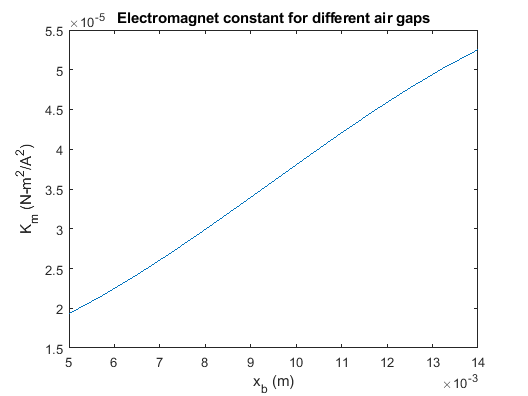

% load nominal model parameters and control paramters
AMP_TYPE = 'VoltPAQ';
[ Lc, Rc, Km, Rs, Mb, Tb, g, K_B, IC_MAX, VMAX_AMP, IMAX_AMP ] = config_maglev( AMP_TYPE );
% 
% loads array showing of electromagnet constant, km, varying w/ air gap
load_variable_km;
% plot electromagnet force constant vs. air gap 
figure;
plot(maglev_km(:,1),maglev_km(:,2));
ylabel('K_m (N-m^2/A^2)');
xlabel('x_b (m)');
title('Electromagnet constant for different air gaps');

% 
% Define electromagnet force constant as uncertain parameter
Km_un = ureal('Km',Km,'range',[min(Km_est) max(Km_est)]);

We can design a PID control based on this uncertain variable and see how it effect the ball position response.

### Linearize Plant with Uncertain Parameters

The nonlinear plant is defined in a Simulink model as shown below.

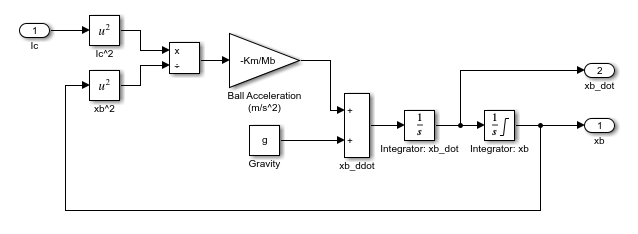

The model is then linearized using the uncertain electromagnet constant. To do this, go to *Linear Analysis *| *Specify block linearization *option in the *Ball Acceleration *block and define the gain using the `Km_un `parameter.

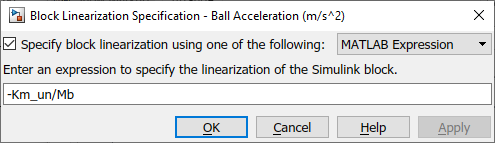

The linearization about the operating air gap and current $(x_{b0}, i_{c0})$ is then performed in the following script. The ranges of the states are defined based on the min/max current of the electromagnet, 0 to 3 A, and the ball travel range, 0 to 14 mm.

% Operating Air Gap (m)
xb0 = 6e-3;
% Nominal current (A)
ic0 = sqrt(Mb * g / Km ) * xb0;
% Open Simulink model with nonlinear model of Maglev
mdlPlant = 'maglev_model';
load_system(mdlPlant);
open_system([mdlPlant '/Maglev Nonlinear Plant']);
%
% Specify linearization input and output points.
io(1) = linio([mdlPlant '/Ic'],1,'openinput');
io(2) = linio([mdlPlant '/Maglev Nonlinear Plant'],1,'openoutput');
% Set operating point and min/max values of states
opspec = operspec(mdlPlant);
% ball position state is known 
opspec.States(1).Known = true;
opspec.States(1).x = xb0;
opspec.States(1).Min = 0;
opspec.States(1).Max = Tb;
opspec.Inputs(1).u = ic0;
opspec.Inputs(1).Min = 0;
opspec.Inputs(1).Max = IC_MAX;
% 
% Compute operating point using these specifications.
options = findopOptions('DisplayReport',false);
op = findop(mdlPlant,opspec,options);
% 
% Obtain the linear plant model at the specified operating point.
GxbIc = linearize(mdlPlant,op,io);
GxbIc.InputName = {'u'};
GxbIc.OutputName = {'y'};
% View transfer function when using nominal value.
tf(GxbIc)

ans =
 
  From input "u" to output "y":
    -32.36
  ----------
  s^2 - 3270
 
Continuous-time transfer function.



% The plant has an integrator and an unstable pole.
bdclose(mdlPlant);

## Current Control

### Electromagnet Coil Model

The electromagnet can be described by the following differential equation


$$v_c(t) = R_c i_c(t) + L_c \frac{d i_c(t)}{dt}$$


Rearranging this to the EOM form


$$\dot{i}_c = \frac{1}{L_c} v_c(t) - \frac{R_c}{L_c} i_c(t)$$


The magnet coil resistance and inductance were identified/measured and used to define the electromagnet coil transfer function model.

% Identified resistance (ohm)
Rc_e = 10.0;
% Identified inductance (H)
Lc_e = 0.374;

### PI Current Control Design

Calculate the required controller gains, $k_{p.c}$ and $k_{i,c}$ , that meet the desired specifications.

% PI controller gains 
Kp_c = 199.4;
Ki_c = 4572.3;

**Note**: Full current contorl design is available in Quanser courseware. Please email [info@quanser.com](http://info@quanser.com) for more information.

## Ball Position Control Design

The ball position is controlled using a PID and feed-forward design. The PID gains are computed through the Control System Tuner app. Because there is a small amount of noise in the ball position sensor, a first-order filter is used in the derivative control, i.e., instead of only taking a direct derivative. Feed-forward control helps to bring the ball up to the operating point where the PID gains are the most effective, since they were design based on the linear model that was linearized about $(x_{b0} \, ,i_{c0})$.

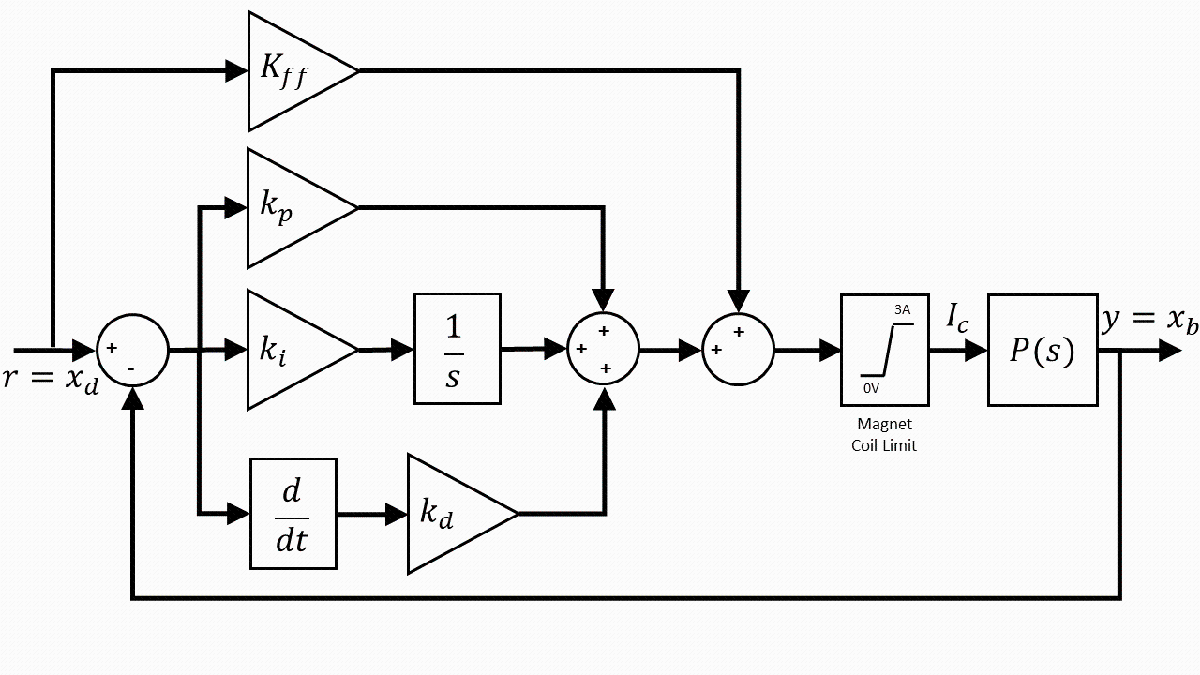

### Ball Position Control Specifications

Ball position control design based on second-order specifications: 

- Percent overshoot <= 5% 

- Settling time <= 0.3 s

The feed-forward gain 

% Percent overshoot and settling time specifications
PO_b = 5;
ts_b = 0.3;
% percent overshoot
zeta_b = abs( log( PO_b / 100 ) ) / sqrt( pi^2 + log( PO_b / 100)^2 );
% 2% settling time: ts_b = 4 / ( zeta_b * wn_b )
wn_b = 4 / ( zeta_b * ts_b );
% Desired 2nd order prototype transfer function
tfdes = tf(wn_b^2,[1 2*wn_b*zeta_b wn_b^2]);
% Feed-forward gain (A/m)
Kff_b = ic0 / xb0;
% Specifications of the second-order low-pass filter
% for the ball (differentiated) velocity signal
wcf = 2 * pi * 75;     % filter cutting frequency (rad/s)
zetaf = 0.9;        % filter damping ratio
% Integral anti-windup maximum for the limiter integrator
% in the ball position loop (A)
MAX_XB_WDUP = 1;
% Rising (and Falling) Setpoint Slew Rate (m/s)
XB_REF_RATE = 5e-3;

### Design Tunable PID Control using Nominal and Uncertain Plant

Create a tunable PID control and design according to the following goals:

- Reference tracking: according to the specifications defined above.

- Maximum loop gain: imposes a maximum gain contraint on the complementary sensitiviy function $T(s) = \frac{L(s)}{1 + L(s)}$ of the system. In this case, we want to 0 dB gain at 4 rad/s with -20 dB/dec afterwards. 

The tuning is performed using the Control System Tuner using both the nominal and uncertain plants. Robust tuning is when tuning is applied to the plant with the uncertain parameters. The performance of the nominal and robust controllers are then compared when simulated and ran the actual hardware.

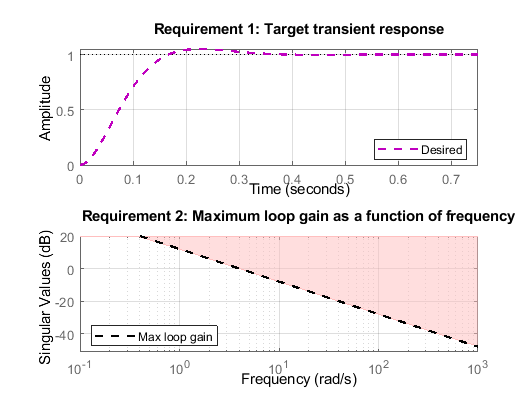

% create tunable PID control
C = tunablePID('C','pid');
% fix set-point and filter constant parameters
C.Tf.Value = 1/500;
C.Tf.Free = false;
% C.InputName={'r';'y'}; C.OutputName='v';
% add analysis point at control input
AP = AnalysisPoint('u');
% 
% Find Y(s)/R(s) closed-loop transfer function (i.e. reference to output)
CL0 = feedback(GxbIc*AP*C,1);
CL0.InputName = 'r';
CL0.OutputName = 'y';
% Nominal tunable closed-loop system
CL0_Nom = feedback(GxbIc.NominalValue*AP*C,1);
CL0_Nom.InputName = 'r';
CL0_Nom.OutputName = 'y';
% 
% Ball setpoint reference tracking goal
Rtrack = TuningGoal.Transient('r','y',tfdes,'step'); 
% Max loop gain: 0 dB gain at 4 rad/s
Rmaxgain = TuningGoal.MaxLoopGain('u',4,1); 
% View goals
viewGoal([Rtrack, Rmaxgain]);

% Setup tuner options
opt_ST = systuneOptions('RandomStart',2);
% NOMINAL PLANT TUNING
disp('Running Tuner on Nominal Plant');

Running Tuner on Nominal Plant


% rng(0), 
[CLNom,fSoftNom] = systune(CL0_Nom,[Rtrack, Rmaxgain],opt_ST);

Final: Soft = 24.7, Hard = -Inf, Iterations = 57
Final: Soft = 24.7, Hard = -Inf, Iterations = 73
Final: Soft = 24.7, Hard = -Inf, Iterations = 58


% [CLNom,fSoftNom] = systune(CL0_Nom,[Rtrack, Rmaxgain]);
showTunable(CLNom);

C =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = -156, Ki = -956, Kd = -2.4, Tf = 0.002
 
Name: C
Continuous-time PIDF controller in parallel form.


CtunedNom = getBlockValue(CLNom,'C');
% UNCERTAIN/ROBUST PLANT TUNING
disp('Running Tuner on Uncertain Plant');

Running Tuner on Uncertain Plant


rng(0), [CL,fSoft] = systune(CL0,[Rtrack, Rmaxgain],opt_ST); 

Nominal tuning:
Design 1: Soft = 24.7, Hard = -Inf
Design 2: Soft = 24.7, Hard = -Inf
Design 3: Soft = 24.7, Hard = -Inf

Robust tuning of Design 2:
Soft: [24.7,210], Hard: [-Inf,-Inf], Iterations = 73
Soft: [27.9,30.3], Hard: [-Inf,-Inf], Iterations = 27
Soft: [29.2,29.2], Hard: [-Inf,-Inf], Iterations = 27
Final: Soft = 29.2, Hard = -Inf, Iterations = 127

Robust tuning of Design 1:
Soft: [24.7,210], Hard: [-Inf,-Inf], Iterations = 57
Soft: [27.9,30.3], Hard: [-Inf,-Inf], Iterations = 27
Soft: [29.2,29.2], Hard: [-Inf,-Inf], Iterations = 27
Final: Soft = 29.2, Hard = -Inf, Iterations = 111

Robust tuning of Design 3:
Soft: [24.7,210], Hard: [-Inf,-Inf], Iterations = 58
Soft: [27.9,30.3], Hard: [-Inf,-Inf], Iterations = 27
Soft: [29.2,29.2], Hard: [-Inf,-Inf], Iterations = 27
Final: Soft = 29.2, Hard = -Inf, Iterations = 112


% [CL,fSoft] = systune(CL0,[Rtrack, Rmaxgain]);
showTunable(CL);

C =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = -179, Ki = -484, Kd = -2.41, Tf = 0.002
 
Name: C
Continuous-time PIDF controller in parallel form.


Ctuned = getBlockValue(CL,'C');

### Robust and Nominal Control Simulations

#### MATLAB Simulations

The step responses of the nominal and robust controllers are first simulated in MATLAB. Because the robust controller uses the uncertain model, it shows the responses for different values of the electromagnet force constant. 

The nominal control is based on the nominal model with a fixed electromagnet constant and is used a reference point. We also simulate the worst-case scenario of the robust controller, which is when the ball is close to the magnet.  

The MATLAB simulations use the linearized model. The more accurate simulation is performed in a Simulink that includes:

- Nonlinear model of the Maglev system

- Electromagnet current limits 0 to 3A

- Ball position limits 0 to 14 mm

- Amplifier limits +/- 24V. 

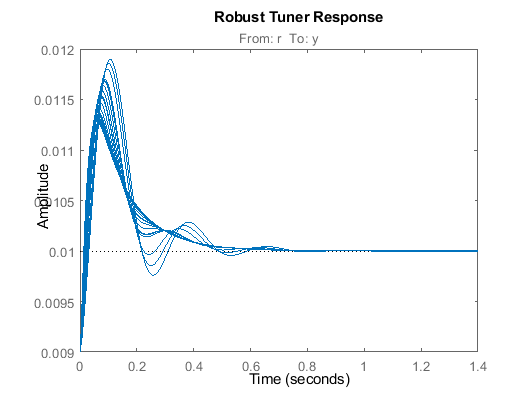

% Simulate 1 mm step about operating point
opt = stepDataOptions('InputOffset',9e-3,'StepAmplitude',1e-3);
figure;
step(CL,opt);
title("Robust Tuner Response");

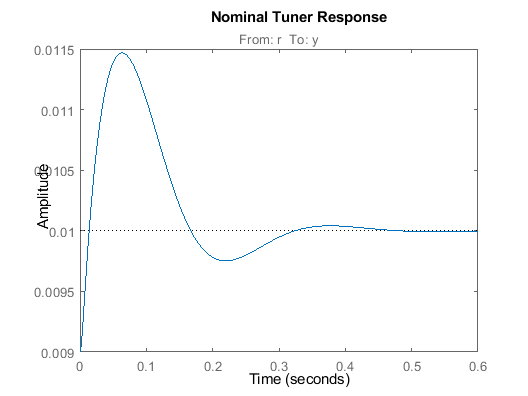

% Simulate closed-loop control with nominal parameters
figure;
step(CLNom,opt);
title("Nominal Tuner Response");

stepinfo(CLNom)

ans = struct with fields:
         RiseTime: 0.0099
    TransientTime: 0.4161
     SettlingTime: 0.4342
      SettlingMin: 0.7527
      SettlingMax: 2.4685
        Overshoot: 146.8452
       Undershoot: 0
             Peak: 2.4685
         PeakTime: 0.0639


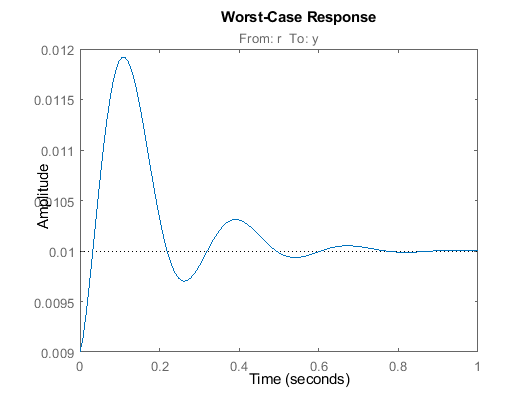

% Find worst-case case and frequency
[wcg,wcu]=wcgain(CL);
% Worst-case is when Km is at the lowest range, i.e., ball is closest to magnet
% Simulated worst-case closed-loop response
CL_wc = usubs(CL,wcu);
figure;
step(CL_wc,opt);
title('Worst-Case Response');

stepinfo(CL_wc)

ans = struct with fields:
         RiseTime: 0.0242
    TransientTime: 0.7101
     SettlingTime: 0.7372
      SettlingMin: 0.7006
      SettlingMax: 2.9194
        Overshoot: 191.9381
       Undershoot: 0
             Peak: 2.9194
         PeakTime: 0.1125


As shown, the overshoot increases and more oscillations occur as the ball approaches the magnet. Given this, we can use robust tuning techniques to design PID gains that will yield a better response over a larger operating range. 

#### **Simulink Simulation**

The MATLAB simulations use the linearized model. A more representative simulation is performed in a Simulink model that includes:

- Nonlinear model of the Maglev system.

- Linear model of the electromagnet with a PI current control.

- Electromagnet current range: 0 to 3 A

- Ball position range: 0 to 14 mm

- Amplifier output voltage range: -24V to 24V. 

- Variable electromagnetic force constant based on experimental data shown earlier.

Open the following Simulink model to simulate either the nominal or robust controllers. You can select which one through the *Manual Switch*.

% Run closed-loop simulation in the following Simulink model
 open("s_maglev_pid.slx");

The results are more in-line with the tracking overshoot and settling time specifications defined earlier.

### Robust Control Implementation

The PID gains generated from the tuner with the uncertain plant are ran on the actual Maglev hardware using Simulink and the [Quanser QUARC Real-Time Control ](https://www.quanser.com/products/quarc-real-time-control-software/)software. 

Note: The Quanser Magnetic Levitation hardware and QUARC Real-Time Control software are required for this.  

% Open Simulink model and run in QUARC
 open('q_maglev_pid_robust.slx');

#### Plot Results 

In the pre-measured data, the ball is first stabilize at an air gap of 9 mm. A +/- 2 mm square wave ball position reference command is then applied in the first cycle and then increased to +/- 3 mm.

% Load saved data
if true
    load('data_maglev_robust_tuning.mat');
end

Plot in new or previously saved data in MATLAB Figure.

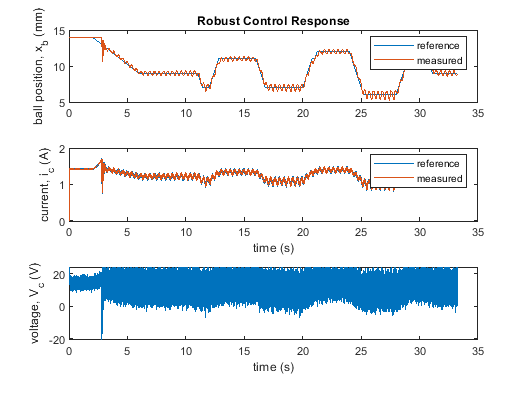

% Load data into variables
t = data_maglev_cntrl_rob(1,:);
xbd = 1e3*data_maglev_cntrl_rob(2,:);
xb = 1e3*data_maglev_cntrl_rob(3,:);
icd = data_maglev_cntrl_rob(4,:);
ic = data_maglev_cntrl_rob(5,:);
vc = data_maglev_cntrl_rob(6,:);
% Plot response
% Magnet Ball Position
figure;
subplot(3,1,1);
plot(t,xbd,t,xb);
title('Robust Control Response');
ylabel('ball position, x_b (mm)');
legend('reference','measured');
% Magnet Current
subplot(3,1,2);
plot(t,icd,t,ic);
xlabel('time (s)');
ylabel('current, i_c (A)');
legend('reference','measured');
% Magnet Voltage
subplot(3,1,3);
plot(t,vc);
xlabel('time (s)');
ylabel('voltage, V_c (V)');

### Nominal Control Implementation

The PID gains generated using the nominal model with a fixed electromagnet constant can be ran on the system. If you have the Magnetic Levitation hardware and QUARC Real-Time Control software, you can run the nominal control PID gains using the following Simulink model.

% Open Simulink model and run in QUARC
 open('q_maglev_pid_nominal.slx');

#### Plot Results 

In the pre-measured data, similar as before the ball is first stabilize at 9 mm. A square wave command about this air gap is then applied starting with +/- 1 mm in the first cycle, +/- 2 mm in the second cycle, and +/- 3 mm is the last.

% Load saved data
if true
    load('data_maglev_pid_nominal_cntrl.mat');
end

Plot in new or previously saved data in MATLAB Figure.

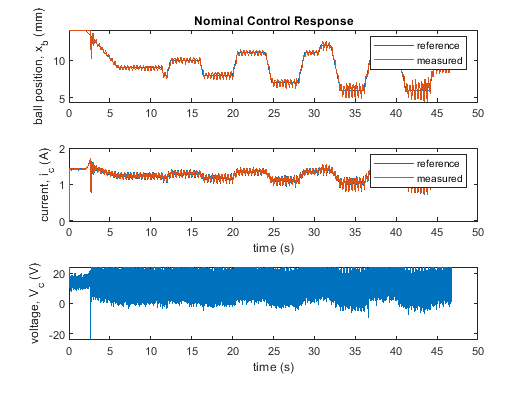

% Load data into variables
t = data_maglev_cntrl_nom(1,:);
xbd = 1e3*data_maglev_cntrl_nom(2,:);
xb = 1e3*data_maglev_cntrl_nom(3,:);
icd = data_maglev_cntrl_nom(4,:);
ic = data_maglev_cntrl_nom(5,:);
vc = data_maglev_cntrl_nom(6,:);
% Plot response
% Magnet Ball Position
figure;
subplot(3,1,1);
plot(t,xbd,t,xb);
title('Nominal Control Response');
ylabel('ball position, x_b (mm)');
legend('reference','measured');
% Magnet Current
subplot(3,1,2);
plot(t,icd,t,ic);
xlabel('time (s)');
ylabel('current, i_c (A)');
legend('reference','measured');
% Magnet Voltage
subplot(3,1,3);
plot(t,vc);
xlabel('time (s)');
ylabel('voltage, V_c (V)');

When comparing response of each control when tracking the reference command, the ball position is more oscillatory in the nominal control as the ball goes closer to the magnet (i.e., smaller air gap). This is inline with what we had noticed in the worst-case simulation reponse. The robust control handles this operation range more effectively. The nominal control less oscillations when the ball is closer to the air gap and further away from the electromagnet. 